## **Driver test program to check Clothoids library**

**Test G1 clothoid**

close all;

% initial point with angle direction
x0     = 0.5;
y0     = 0;
theta0 = 1;

% final point with angle direction
x1     = 0.5;
y1     = 0.5;
theta1 = 1;

fprintf('Testing G1 Clothoid interpolation\n');

Testing G1 Clothoid interpolation


fprintf('initial point (%g,%g) initial angle = %g\n', x0, y0, theta0);

initial point (0.5,0) initial angle = 1


fprintf('final point (%g,%g) final angle = %g\n', x1, y1, theta1);

final point (0.5,0.5) final angle = 1



% compute clothoid parameters
C = ClothoidCurve();
C.build_G1( x0, y0, theta0, x1, y1, theta1 );

fprintf('Computed parameters: k = %g, k'' = %g, L = %g\n', C.kappaBegin(), C.dkappa(), C.length() );

Computed parameters: k = 6.6096, k' = -25.5923, L = 0.516531


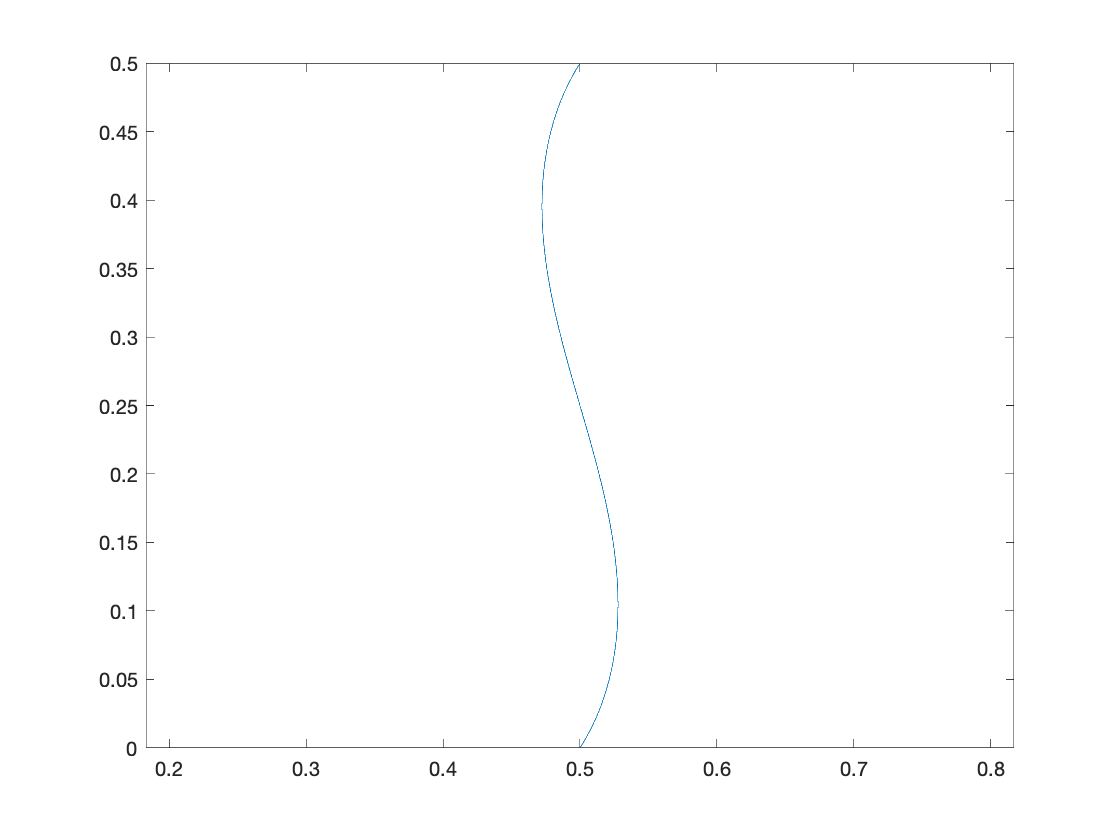


C.plot();
axis equal